Load processed data from file.

load letterfeatures

### Fit, predict, and evaluate

Try a simple kNN.

kNNmodel = fitcknn(traindata,"Character")

kNNmodel =   ClassificationKNN
           PredictorNames: {1×25 cell}
             ResponseName: 'Character'
    CategoricalPredictors: []
               ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
           ScoreTransform: 'none'
          NumObservations: 2906
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


Evaluate the model on the test data.

loss(kNNmodel,testdata)

ans = 0.2248

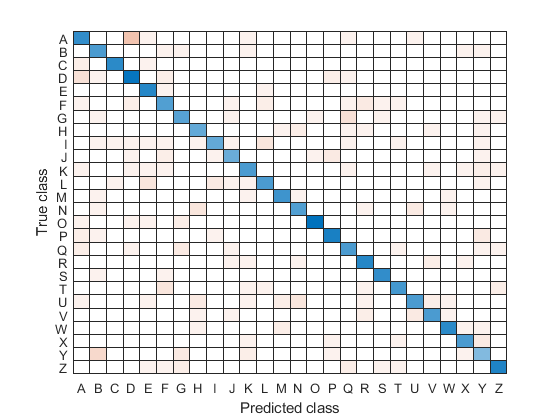

predLetter = predict(kNNmodel,testdata);
confusionchart(testdata.Character,predLetter);

Try more neighbors. Because kNN is distance-based, add normalization.

kNNmodel = fitcknn(traindata,"Character","NumNeighbors",10,"Standardize",true)

kNNmodel =   ClassificationKNN
           PredictorNames: {1×25 cell}
             ResponseName: 'Character'
    CategoricalPredictors: []
               ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
           ScoreTransform: 'none'
          NumObservations: 2906
                 Distance: 'euclidean'
             NumNeighbors: 10


  Properties, Methods


loss(kNNmodel,testdata)

ans = 0.1964

Try a different number of neighbors but add weighting by distance.

kNNmodel = fitcknn(traindata,"Character","NumNeighbors",5,"Standardize",true, ...
    "DistanceWeight","squaredinverse");
loss(kNNmodel,testdata)

ans = 0.1628

Try a different approach: an ensemble of bagged trees.

rng(123)
TBmodel = fitcensemble(traindata,"Character","Method","Bag","Learners","tree","NumLearningCycles",30);
loss(TBmodel,testdata)

ans = 0.1505

Looks like that's about as good as it's going to get. Go back to the weighted kNN model with k = 5.

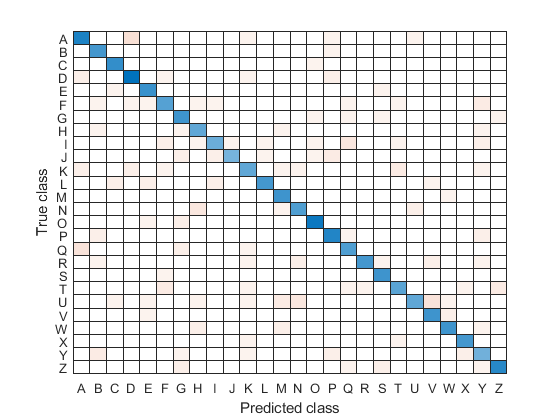

predLetter = predict(kNNmodel,testdata);
confusionchart(testdata.Character,predLetter);

### Analyze misclassifications

Get the confusion matrix data.

cm = confusionmat(testdata.Character,predLetter);
% Split into correct and incorrect classifications
yes = diag(cm);
no = cm - diag(yes);

Get misclassification rate for each letter.

misratebyletter = sum(no,2)./sum(cm,2);

Convert to a table with letter names and misclassification rate.

letters = categories(traindata.Character);
misratebyletter = table(letters,misratebyletter,'VariableNames',["Letter","MisClassRate"]);
% Sort by worst misclassification
misratebyletter = sortrows(misratebyletter,"MisClassRate","descend")

misratebyletter = 26×2 table
    Letter    MisClassRate
    ______    ____________

     'U'        0.39535   
     'I'        0.35135   
     'K'         0.2973   
     'J'        0.29032   
     'Y'        0.28125   
     'T'        0.27027   
     'F'        0.26316   
     'Q'        0.21622   
     'R'        0.20513   
     'N'        0.19444   
     'A'        0.19149   
     'L'        0.18421   
     'Z'        0.14286   
     'W'        0.13514   
     'H'        0.13333   
     'D'        0.12245   


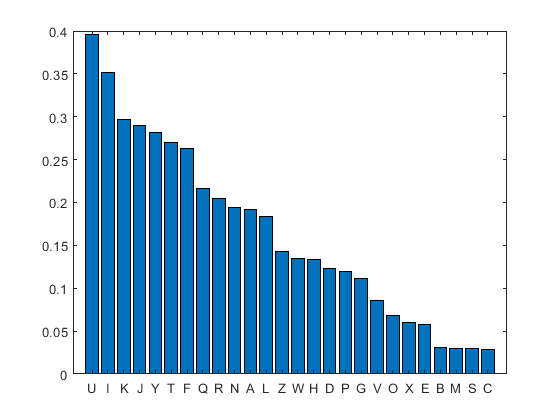

bar(misratebyletter.MisClassRate)
xticks(1:26)
xticklabels(misratebyletter.Letter)

Look at individual misclassification examples.

letter = "U";

Get the observations with this true class that were misclassified as something else.

misclassidx = (testdata.Character == letter) & (predLetter ~= testdata.Character);

Make a table of the misclassified observations, with the predicted letter included.

badpred = testdata(misclassidx,:);
badpred.Prediction = predLetter(misclassidx);

Get the associated data files. Read the raw data from each file and plot it. Label the plot with the prediction.

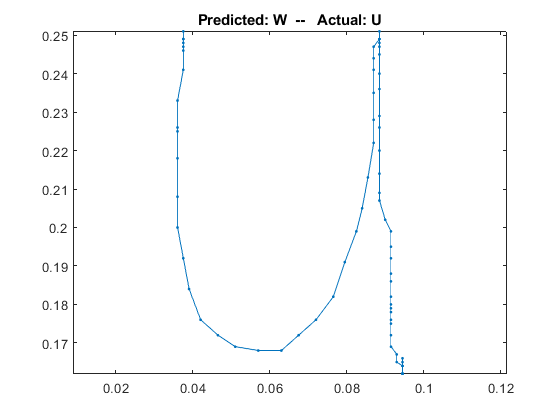

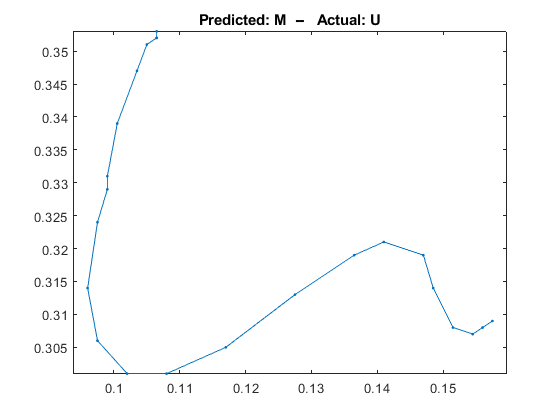

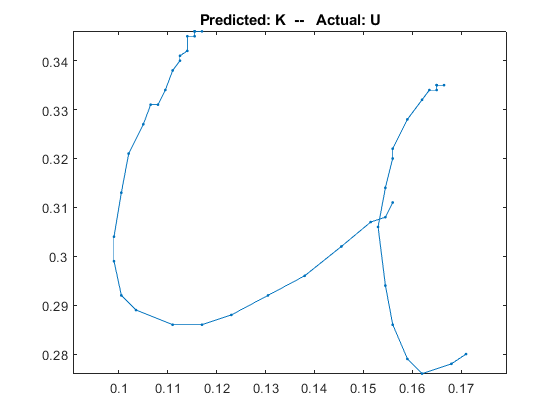

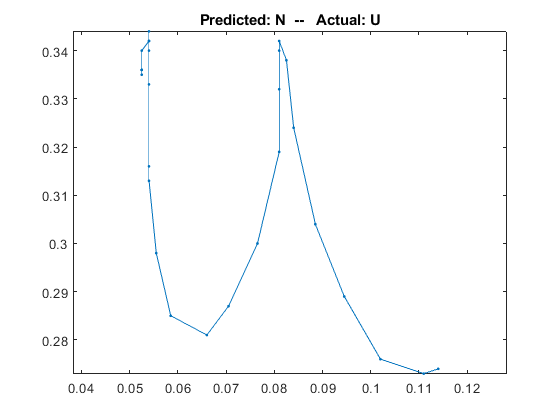

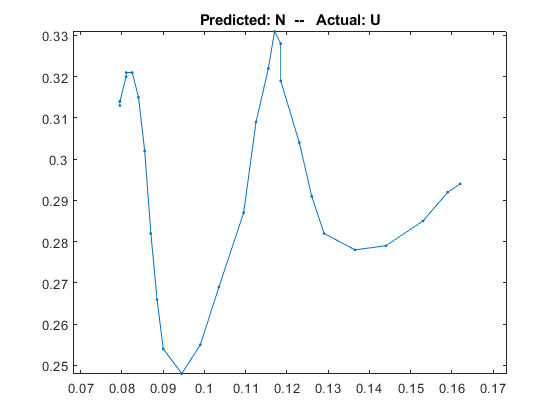

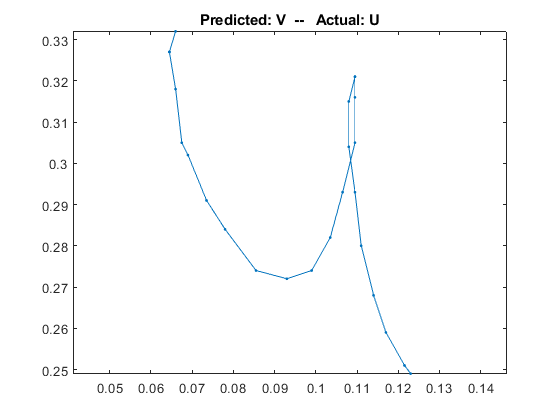

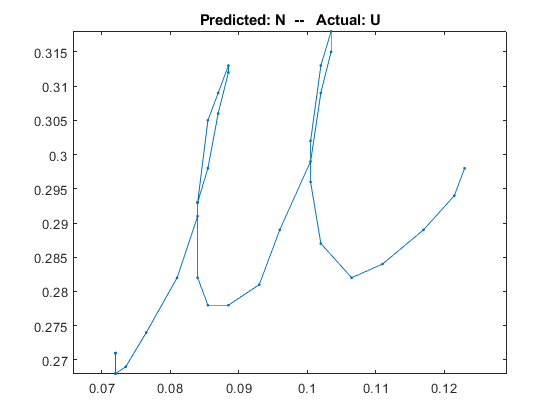

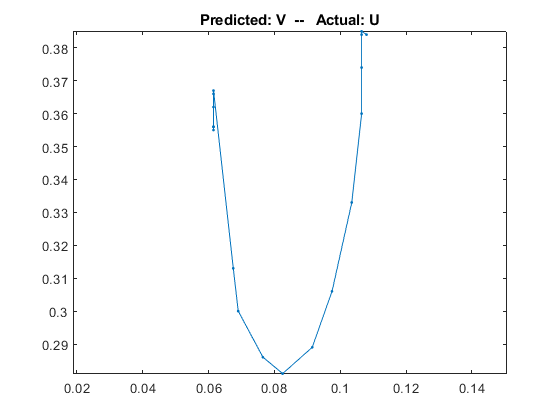

badfiles = testfiles(misclassidx);
for k = 1:numel(badfiles)
    badletter = readtable("Data"+filesep+badfiles(k));
    figure
    plot(1.5*badletter.X,badletter.Y,".-")
    title("Predicted: "+string(badpred.Prediction(k))+"  --   Actual: "+letter)
    axis equal
end